# Muestreo, ventanas y descomposición espectral

## Periodograma

Hacer paso a paso:

**Entrada de longitud par con tasa de muestreo**

[https://la.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html](https://la.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html)

fs = 1000;
t = 0:1/fs:1-1/fs;
x = cos(2*pi*100*t) + randn(size(t));

figure
plot(t,x)

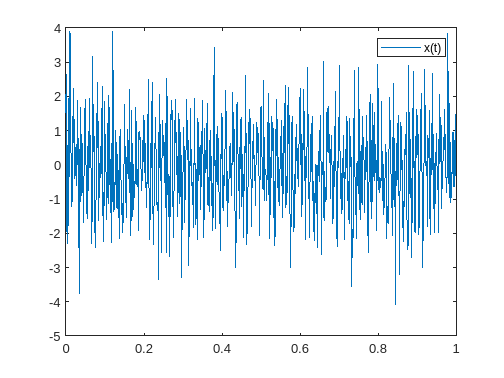

legend("x(t)")

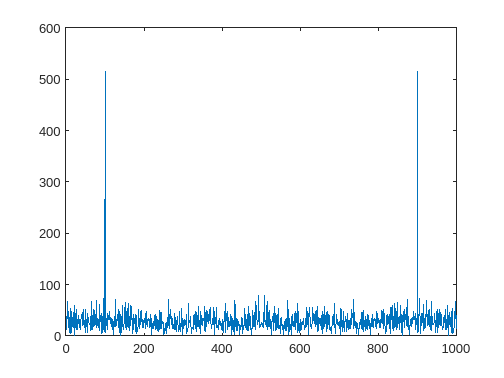

N = length(x);
xdft = fft(x);

%Solo pára ver la magnitud de la transformada de fourier
figure
plot(abs(xdft))


xdft = xdft(1:N/2+1);
psdx = (1/(fs*N))*abs(xdft).^2

psdx =     0.0011    0.0002    0.0046    0.0011    0.0014    0.0022    0.0004    0.0001    0.0000    0.0005    0.0029    0.0000    0.0023    0.0000    0.0007    0.0013    0.0004    0.0021    0.0008    0.0003    0.0016    0.0000    0.0035    0.0009    0.0003    0.0004    0.0002    0.0028    0.0002    0.0004    0.0009    0.0016    0.0011    0.0010    0.0003    0.0001    0.0002    0.0006    0.0018    0.0014    0.0013    0.0020    0.0004    0.0005    0.0027    0.0014    0.0006    0.0006    0.0001    0.0028


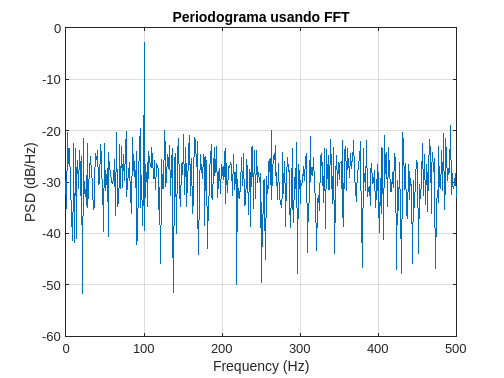

psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2; %Teorema de Nyquist

plot(freq,pow2db(psdx))
grid on
title("Periodograma usando FFT")
xlabel("Frequency (Hz)")
ylabel("PSD (dB/Hz)")

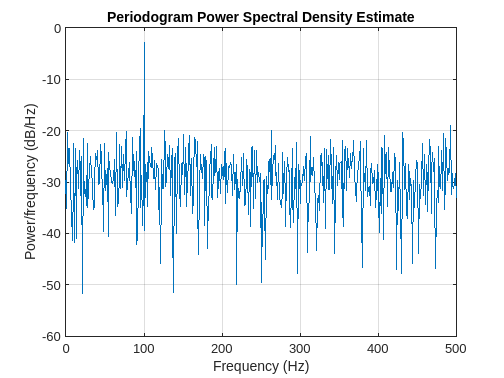

figure
periodogram(x,rectwin(N),N,fs)

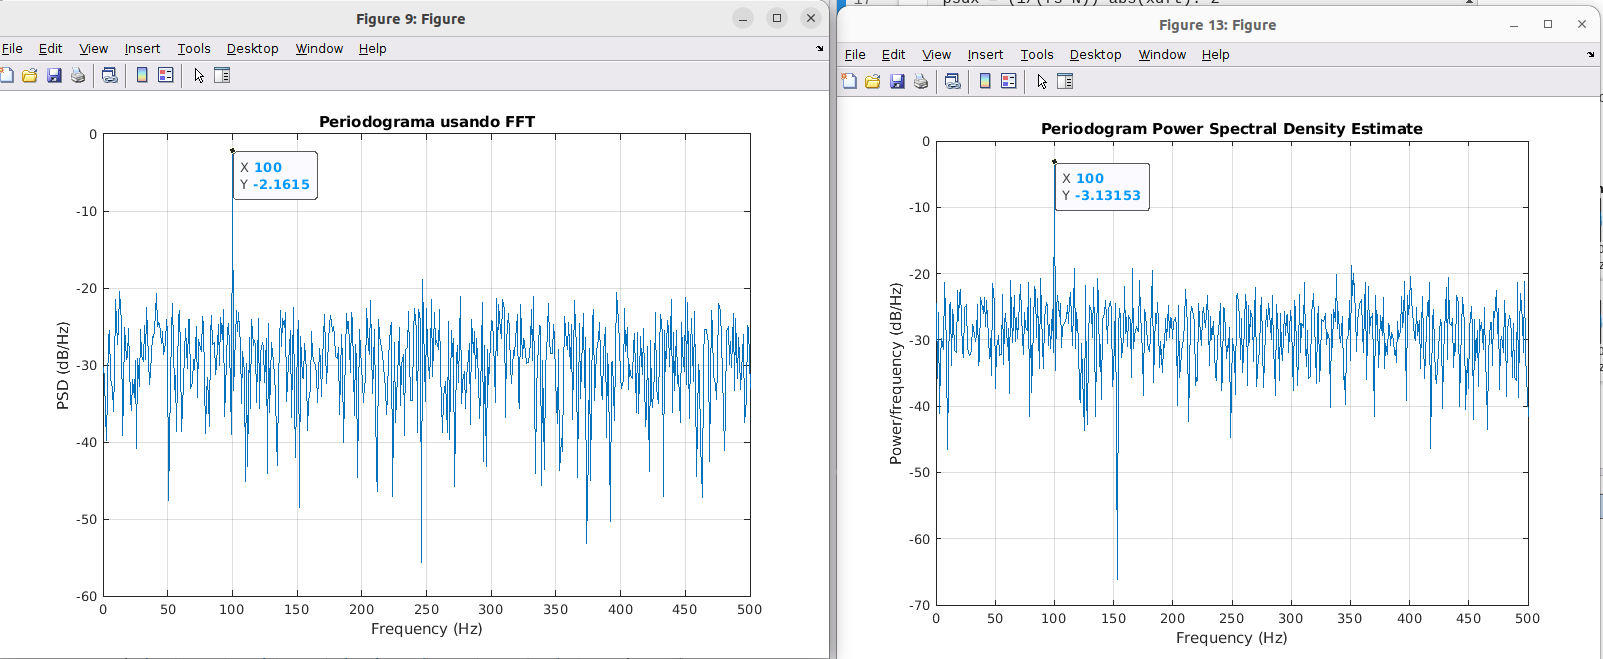

## Muestreo

1.- Definir las siguientes señales y graficarlas en tiempo continuo:


$$\begin{array}{l}
x_1 =\cos \left(4*2\pi t\right)+\cos \left(4\ldotp 5*2\pi t\right)\\
x_2 =\cos \left(4*2\pi t\right)+\cos \left(8*2\pi t\right)\\
x_3 =\cos \left(4*2\pi t\right)+0\ldotp 001\cos \left(8*2\pi t\right)
\end{array}$$


syms t

x = cos(4*2*pi*t)+cos(4.5*2*pi*t) %Hz

$$x = \cos\left(8\,\pi \,t\right)+\cos\left(9\,\pi \,t\right)$$

2.- Tomar muestras con 3 frecuencias de muestreo en un intervalo entre $t=\left(0,40\right)$. Graficar las señales discretas


$$\begin{array}{l}
f_{\textrm{s1}} =3\\
f_{\textrm{s2}} =6\\
f_{\textrm{s3}} =12\\

\end{array}$$


fs = 3; %Hz
t1 = 0:1/fs:40;

x1 = double(subs(x,t,t1));
N = length(x1)

N = 121

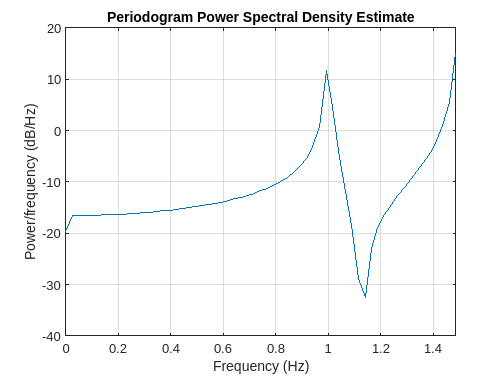


figure
periodogram(x1,rectwin(N),N,fs)


fs = 12;%Hz
t1 = 0:1/fs:40;

x1 = double(subs(x,t,t1));
N = length(x1)

N = 481

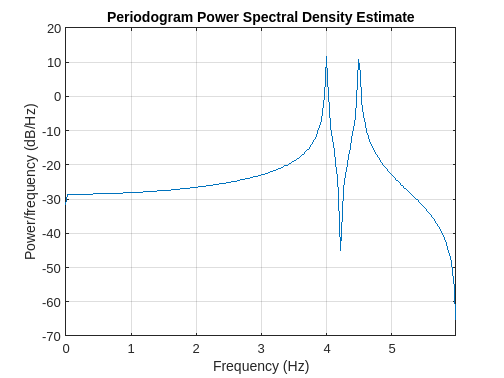


figure
periodogram(x1,rectwin(N),N,fs)

## Ventanas

Aplicar una ventana rectangular (default), otra de alto rango dinamico y otra de alta resolución a las 3 señales anteriores con $f_{s\;} =100\mathrm{Hz}$. Sacar el periodograma.

[https://la.mathworks.com/help/signal/ug/windows.html](https://la.mathworks.com/help/signal/ug/windows.html)

x = cos(4*2*pi*t)+0.001*cos(4.2*2*pi*t) %Hz

$$x = \cos\left(8\,\pi \,t\right)+\frac{\cos\left(\frac{42\,\pi \,t}{5}\right)}{1000}$$

fs = 100;%Hz
t1 = 0:1/fs:40;

x1 = double(subs(x,t,t1));
N = length(x1)

N = 4001

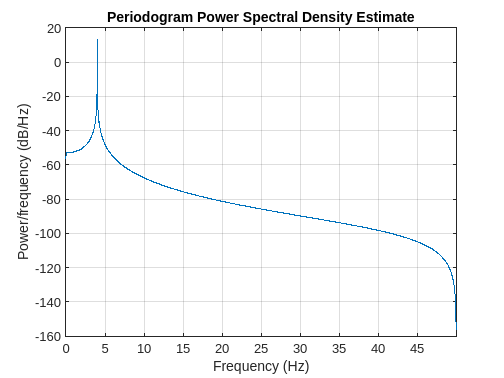


figure
periodogram(x1,rectwin(N),N,fs)

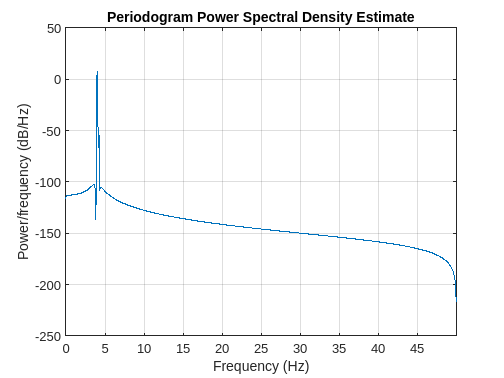


figure
periodogram(x1,flattopwin(N),N,fs)